% This m-file executes simulation and generates figures for the main
% analysis of "Covid-19 and Output in Japan" by Daisuke Fujii and Taisuke
% Nakata

clear variables
close all
iPC=0;
home = '/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Covid19OutputJapan.github.io/archives/20210223/';
% if iPC ==1
%     home = '\Users\shcor\Dropbox\fujii_nakata\Website\Codes\';
% else
%     home = '/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/';
% end
cd(home);
LastWeek = '20210216';
Last2Week = '20210209';


%====================== Program parameter values ======================%
figure_save = 0;    % 0 = figures won't be saved, 1 = they will be saved
mat_save = 0;    % 0 = figures won't be saved, 1 = they will be saved
% in the "Figure" folder
fs = 16;            % common font size for many figures
xlim_tradeoff = [1,2.5];
iDrawUB = 0;          % 0 = create quasi-UB without simulations, 1 = create UB with simulations
Nsim = 30000;         % if iDrawUB=1, this is the number of draws you use.
%======================================================================%

%====================== Model parameter values ======================%
pref = 'Japan';        % prefecture to be analyzed
POP0 = 125710000;      % initial population
%gamma = 0.68; 
gamma = 7/5;          % recovery rate from Covid
k = 2;                 % exponent of (1-h*alpha)
hconstant = 1;         % 0 = without intercept, 1 = with intercept for h regression
TargetAlpha = 0.5:0.1:3;      % values of alpha we simulate results
AlphaVals = [1.2,1.65,2.5];   % benchmark alpha we plot time-series figures
SimPeriod = 52;        % simulation period in weeks
medical_start_date = datetime(2021,3,18);
elderly_start_date = datetime(2021,4,1);
% VacStartDate = datetime(2021,4,1);         % time until the start of vaccination process
% VacPace = 0.8*(3000000/2); % number of vaccinated persons per week (steady pace)
% VacDuration = 12;       % time until vaccination pace reaches its steady pace
RetroPeriod = 17;      % retroactive periods used to estimate gamma and delta
wl = [1,2];            % Results as of these weeks ago
%====================================================================%


%--- Import data ---%
% Covid data are recorded at weekly frequencies (Mon-Sun)
% The first week start on January 20 (Mon), 2020
covid = importdata([home 'Covid_weekly.csv']);  % Import weekly Covid data
Data = covid.data(strcmp(covid.textdata(2:end,1),pref),:);
date = Data(:,1) + 21916;
date = datetime(date,'ConvertFrom','excel');
N = Data(:,2);
dD = Data(:,3);
M = Data(:,4);
GDP = Data(:,5);
Tdata= size(Data,1);    % Data period in weeks
xtick1 = 1:13:Tdata;
dateEN = datestr(date,'mmm-dd');
SimDate = date(end)+7:7:date(end)+7*SimPeriod;
SimDateEN = datestr(SimDate);
M = 1+0.01*M;
TdataGDP = Tdata-sum(isnan(GDP));
RetroH = TdataGDP-4;
VacStart = find(SimDate == datetime(2021,4,1), 1);
medical_start = find(SimDate == medical_start_date, 1);
elderly_start = find(SimDate == elderly_start_date, 1);
End2020 = find(date == datetime(2021,1,7), 1);
Month = string(datetime(date,'ConvertFrom','excel','Format','MMM-yy'));

%--- Update forecast error data ---%
if iPC==1
    FE = load('\Users\shcor\Dropbox\fujii_nakata\Website\Codes\Forecast.mat');
else
    FE = load('/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/Forecast.mat');
end
% dDActual = [FE.dDActual;dD(end)];
% dNActual = [FE.dNActual;N(end)];
% if dNActual(end) ~= dNActual(end-1) && length(dNActual) == Tdata
%     if iPC==1
%         save('\Users\shcor\Dropbox\fujii_nakata\Website\Codes\Forecast.mat','dDActual','dNActual','-append');
%     else
%         save('/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Forecast.mat','dDActual','dNActual','-append');
%     end
% end




%--- Constructing the reference level of output ---%
potentialGDP = zeros(52*3,1);       % potential GDP for the next 3 years
potentialGDP(1) = (548182/(1.0122))*(1.0063^(1/12));
for i = 2:length(potentialGDP)
    if i <= 13
        potentialGDP(i) = potentialGDP(i-1)*(1.0063^(1/52));
    elseif i <= 52
        potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
    elseif i <= 104
        potentialGDP(i) = potentialGDP(i-1)*(1.0024^(1/52));
    elseif i <= 156
        potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
    end
end
% gapGDP = zeros(length(potentialGDP),1);
% gapGDP(1) = 0.0166;
% for i = 2:length(gapGDP)
%     gapGDP(i) = gapGDP(i-1)*(0.975^(12/52));
% end
referenceGDP = potentialGDP.*(1+0.0166);
referenceGDP(1:2) = [];


%--- Impute alpha (regress alpha on M)---%
Malt=M;
Malt(50)=0.5*(Malt(49)+Malt(51));
alpha = (1 - GDP(1:TdataGDP)./referenceGDP(1:TdataGDP));   % output loss in percentage
X = M(TdataGDP-17:TdataGDP);
Y = alpha(TdataGDP-17:TdataGDP);
XC = [ones(length(X),1), X];
s = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
reg = XC*s;
r = Y - reg;
SSE = sum(r.^2);
eps_p = zeros(Tdata-TdataGDP,1);
eps_p(1) = r(end);
for i = 1:Tdata-TdataGDP-1
    eps_p(i+1) = 1*eps_p(i);
end
alpha_pred = s(1)+s(2)*Malt(TdataGDP+1:Tdata)+eps_p;

alpha = [alpha;alpha_pred];


%--- Plot mobility data ---%
% figure(2)
% yyaxis left
% plot(M,'k','LineWidth',1.5)
% ylabel('Mobility')
% yyaxis right
% plot(GDP,'b-.','LineWidth',1.5)
% ylabel('GDP')
% xlim([1 Tdata])
% xticks(xtick1)
% xticklabels(dateEN(xtick1))
% legend('Mobility (left axis)','GDP (right axis)','FontSize',16,'Location','north');
% ax = gca;
% ax.YAxis(1).Color = 'k';
% ax.YAxis(2).Color = 'b';
% ax.YAxis(1).FontSize = fs;
% ax.YAxis(2).FontSize = fs;
% ax.XAxis.FontSize = fs;


%--- Regress mobility on alpha to estimate the elasticity h ---%
Y = M(4:TdataGDP);
X = alpha(4:TdataGDP);
if hconstant == 0
    Y = Y - 1;
    h_all = (X'*X)\X'*Y;              % OLS estimate of h
    reg = X*h_all;
    r = Y - reg;                % r is the residuals, which is the observed minus fitted values
    SSE = sum(r.^2);            % SSE is the sum of squared errors
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_all_se=sqrt(MSE/sum(X.^2));   % standard error of h
elseif hconstant == 1
    XC = [ones(length(X),1), X];
    h_all = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
    reg = XC*h_all;
    r = Y - reg;
    SSE = sum(r.^2);
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_all_se = zeros(2,1);
    h_all_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
    h_all_se(2)=sqrt(MSE/sum(XC(:,2).^2));
end

Y = M(TdataGDP-RetroH:TdataGDP);
X = alpha(TdataGDP-RetroH:TdataGDP);
if hconstant == 0
    Y = Y - 1;
    h = (X'*X)\X'*Y;              % OLS estimate of h
    reg = X*h;
    r = Y - reg;                % r is the residuals, which is the observed minus fitted values
    SSE = sum(r.^2);            % SSE is the sum of squared errors
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_se=sqrt(MSE/sum(X.^2));   % standard error of h
elseif hconstant == 1
    XC = [ones(length(X),1), X];
    h = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
    reg = XC*h;
    r = Y - reg;
    SSE = sum(r.^2);
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_se = zeros(2,1);
    h_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
    h_se(2)=sqrt(MSE/sum(XC(:,2).^2));
end



% 
% figure(100)
% if hconstant == 0
%     scatter(X,Y,60,'filled')
%     hold on
%     plot(X,reg,'LineWidth',1.5)
% elseif hconstant == 1
%     scatter(XC(:,2),Y,60,'filled')
%     hold on
%     plot(XC(:,2),reg,'LineWidth',1.5)
% end
% xlabel('Output loss (%)');
% ylabel('Mobility');
% aa = gca;
% aa.YAxis.FontSize = fs;
% aa.XAxis.FontSize = fs;
% hold off



%--- Compute the history of S, I, R, D in the data period ---%
S = zeros(Tdata+1,1);
I = zeros(Tdata+1,1);
R = zeros(Tdata+1,1);
D = zeros(Tdata+1,1);
S(1)=POP0;
for i = 1:Tdata
    S(i+1)=S(i)-N(i);
    I(i+1)=I(i)+N(i)-gamma*I(i)-dD(i);
    R(i+1)=R(i)+gamma*I(i);
    D(i+1)=D(i)+dD(i);
    if i > TdataGDP
        GDP(i) = referenceGDP(i)*(1-alpha(i));
    end
end

%--- Compute the history of time-varying parameters ---%

delta = (D(2:Tdata+1)-D(1:Tdata))./I(1:Tdata);                              % death rate
beta_tilde = -POP0*((S(2:Tdata+1)-S(1:Tdata))./(S(1:Tdata).*I(1:Tdata)));   % overall infection rate
ERN = (S(1:end-1)/POP0).*beta_tilde./(gamma+delta);                                        % effective reproduction number
if hconstant == 0
    beta = beta_tilde./(1+h_all*alpha).^k;                                      % raw infection rate
elseif hconstant == 1
    %     beta = beta_tilde./(h(1)+h(2)*alpha).^k;
    beta = beta_tilde./(1+(h_all(2)/h_all(1))*alpha).^k;
end
AverageAlpha2020 = 100*mean([alpha(1);alpha(2);alpha(1:End2020)]);


% %--- Plot varabiles in the data period ---%
% figure(1)
% plot(N,'k','LineWidth',2)
% xlim([1 Tdata])
% xticks(xtick1)
% yticks([0 10000 20000 30000 40000])
% xticklabels(dateEN(xtick1))
% xtickangle(45)
% ax = gca;
% ax.YAxis.FontSize = 16;
% ax.XAxis.FontSize = 16;
% ax.YAxis.Exponent = 0;
% ytickformat('%,6.0f')


% VarList = ["S","I","R","D","N","GDP"];
% VarName = ["S","I","R","D","N","Y"];

% for i = 1:length(VarList)
%     figure(4)
%     subplot(2,3,i)
%     plot(eval(VarList(i)),'k','LineWidth',2)
%     xlim([1 Tdata])
%     title(VarName(i),'FontWeight','normal')
%     xticks(xtick1)
%     xticklabels(dateEN(xtick1))
%     xtickangle(45)
%     if i == 5
%         ax = gca;
%         ax.YAxis.Exponent = 0;
%         ytickformat('%,6.0f')
%     end
%     if i == length(VarList)
%         hold on
%         plot(referenceGDP,'k--','LineWidth',2)
%     end
% end


%--- Plot parameters in the data period ---%
ParamList = ["alpha","ERN","beta","delta"];
ParamName = ["$\alpha$ (decline in Y)","Effective reproduction number",...
    "$\beta$ (raw infection rate)","$\delta$ (death rate)"];
% for i = 1:4
%     figure(3)
%     subplot(2,2,i)
%     plot(eval(ParamList(i)),'k','LineWidth',2)
%     xlim([1 Tdata])
%     title(ParamName(i),'Interpreter','latex','FontSize',14,'FontWeight','normal')
%     xticks(xtick1)
%     xticklabels(dateEN(xtick1))
%     xtickangle(45)
%     if i == 2
%         ylim([0 2.5]);
%         yline(1);
%     end
%     if i == 3
%         ylim([0 5]);
%     end
%     if i == 4
%         ylim([0 0.1]);
%     end
% end


%%%%%%%%%%%%%%%%% Projection starts here %%%%%%%%%%%%%%%%%

%--- Construct time series of parameters ---%
gammaT = gamma*ones(SimPeriod,1);
beta_sample = beta(end-RetroPeriod+1:end);
beta_average = mean(beta_sample);
betaT = mean(beta_sample)*ones(SimPeriod,1);
delta_sample = delta(end-RetroPeriod+1:end);
delta_average = mean(delta_sample);

pace = 3500000;
medical = 3700000*0.8;
elderly = 36000000*0.8;
ordinary = (125710000-36000000-3700000)*0.8;
elderly_total = 36000000;

[V,deltaT,VT,real_pace] = vaccine_path(pace,SimPeriod,medical,elderly,ordinary,medical_start,elderly_start,4,0.9,delta_average,elderly_total);


%--- Construct time series of parameters ---%
InitialValues = [S(end),I(end),R(end),D(end)];

VShots = sum(VT,2);
CumD = zeros(1,length(TargetAlpha));
AverageAlpha = zeros(1,length(TargetAlpha));
LagResults = zeros(2,length(TargetAlpha),length(wl));
ParamList2 = ["alpha2","ERN2","beta2","delta2"];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Forecast error analysis (using next week's data) %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if iPC==1
  NextD = load('\Users\shcor\Dropbox\fujii_nakata\Website\Codes\Japan20210302.mat');
else
  NextD = load('/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/Japan20210302.mat');
end

AlphaNext = NextD.alpha(end);
[CumDNext,AverageAlphaNext,SimDataNext,SimNNext]=Covid_projection(InitialValues,AlphaNext,betaT,gammaT,deltaT,V,h,k,POP0,hconstant);
dDForecast = [FE.dDForecast;(CumDNext-D(end))];
dNForecast = [FE.dNForecast;SimNNext];
if dNForecast(end) ~= dNForecast(end-1) && length(dNForecast) == NextD.Tdata
  if iPC==1
      save('\Users\shcor\Dropbox\fujii_nakata\Website\Codes\Forecast.mat','dDForecast','dNForecast','-append');
  else
      save('/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/Forecast.mat','dDForecast','dNForecast','-append');
  end
end





%--- Sensitivity parameters ---%
% BetaVals = beta_average*[1.05, 1, 0.95];
% KVals = [1.5, 2, 2.5];
% HVals = [0.8, 1, 1.2];
% 
% VacStartVals = [16, 12, 20];
% VacPaceVals = [0.5*VacPace, VacPace, 2*VacPace];
% FrontLoadingVals = [0.5, 1, 1.5];
% SA = zeros(3,length(TargetAlpha),4);    % matrix to contain the results of sensitivity analysis
AlphaIndexVariables = zeros(SimPeriod,6,length(AlphaVals));    % matrix to contain the projected variables for certain alpha values

%--- Simulation for different alpha values ---%
for i = 1:length(TargetAlpha)

## Baseline projection %%%

    alphaT = zeros(SimPeriod,1);
    alphaT(1:26) = flip(0:0.01*TargetAlpha(i)*4/(26-1):(0.01*TargetAlpha(i)*4))';
    [CumD(i),AverageAlpha(i),SimData,SimN]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,h,k,POP0,hconstant);

## Results from previous weeks %%%

%     for j = 1:length(wl)
%         wlag = wl(j);
%         VacStartL = VacStart + wlag;
%         VL = zeros(SimPeriod,1);
%         VL(VacStartL-1:VacStartL+VacDuration-1) = 0:VacPace/VacDuration:VacPace;
%         VL(VacStartL+VacDuration:end) = VacPace;
%         InitialValuesL = [S(end-wlag),I(end-wlag),R(end-wlag),D(end-wlag)];
%         betaL = mean(beta(end-RetroPeriod+1-wlag:end-wlag))*ones(SimPeriod,1);
%         %         deltaL = mean(delta(end-RetroPeriod+1-wlag:end-wlag))*ones(SimPeriod,1);
%         delta_averageL = mean(delta(end-RetroPeriod+1-wlag:end-wlag));
%         delta_ssL = delta_averageL*(0.09/1.27);
%         deltaL = delta_averageL*ones(SimPeriod,1);
%         deltaL(VacStart+3:VacStart+3+9+13) = delta_averageL:(delta_ssL-delta_averageL)/22:delta_ssL;
%         deltaL(VacStart+3+9+13+1:end) = delta_ssL;
%         [LagResults(1,i,j),LagResults(2,i,j)]=Covid_projection(InitialValuesL,alphaT,betaL,gammaT,deltaL,VL,h,k,POP0,hconstant);
%     end

## Beta sensitivity %%%

%     for j = 1:length(BetaVals)
%         betaS = BetaVals(j)*ones(SimPeriod,1);
%         [SA(j,i,1)]=Covid_projection(InitialValues,alphaT,betaS,gammaT,deltaT,V,h,k,POP0,hconstant);
%     end

## h sensitivity %%%

%     for j = 1:length(HVals)
%         if hconstant == 0
%             HS = HVals(j);
%         elseif hconstant == 1
%             HS = h;
%             HS(2) = h(2)*HVals(j);
%         end
%         [SA(j,i,2)]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,HS,k,POP0,hconstant);
%     end

## k sensitivity %%%

%     for j = 1:length(KVals)
%         kS = KVals(j);
%         [SA(j,i,3)]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,h,kS,POP0,hconstant);
%     end

## VacPace sensitivity %%%

%     for j = 1:length(VacPaceVals)
%         VacPaceS = VacPaceVals(j);
%         VS = zeros(SimPeriod,1);
%         VS(VacStart-1:VacStart+VacDuration-1) = 0:VacPaceS/VacDuration:VacPaceS;
%         VS(VacStart+VacDuration:end) = VacPaceS;
%         [SA(j,i,4)]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,VS,h,k,POP0,hconstant);
%     end
end

## Time series figures (variables and parameters) %%%

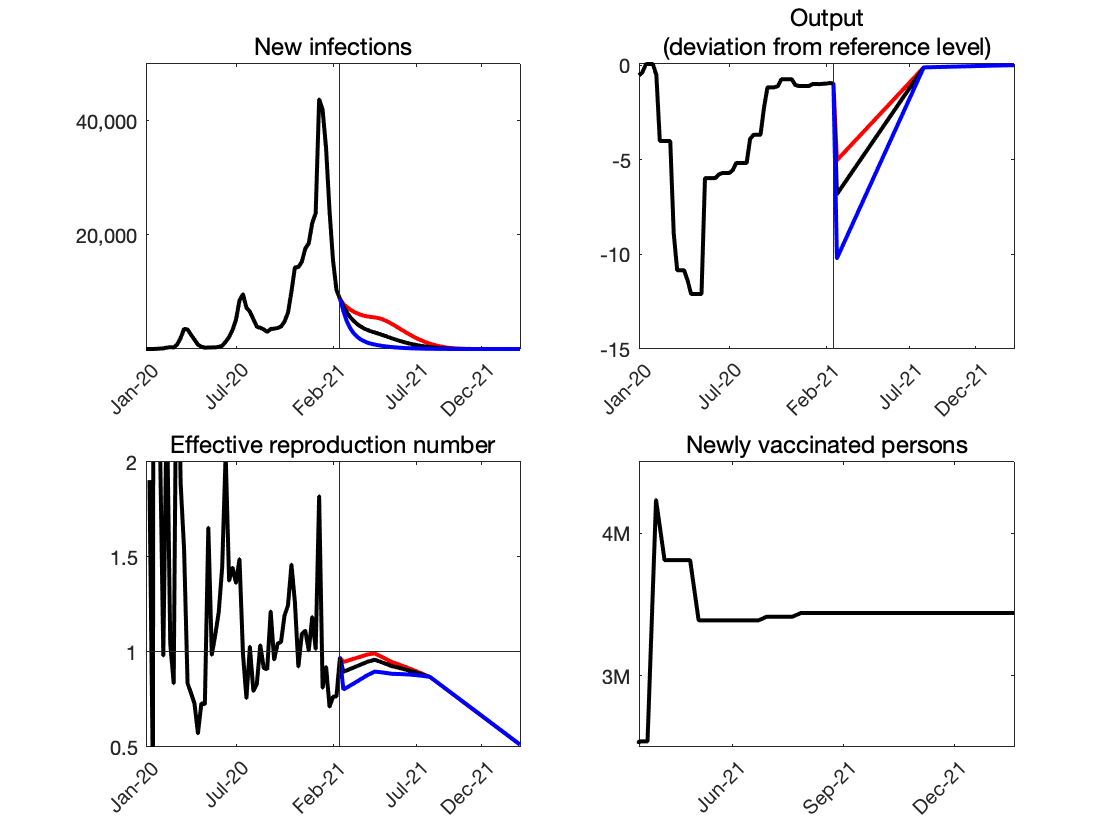

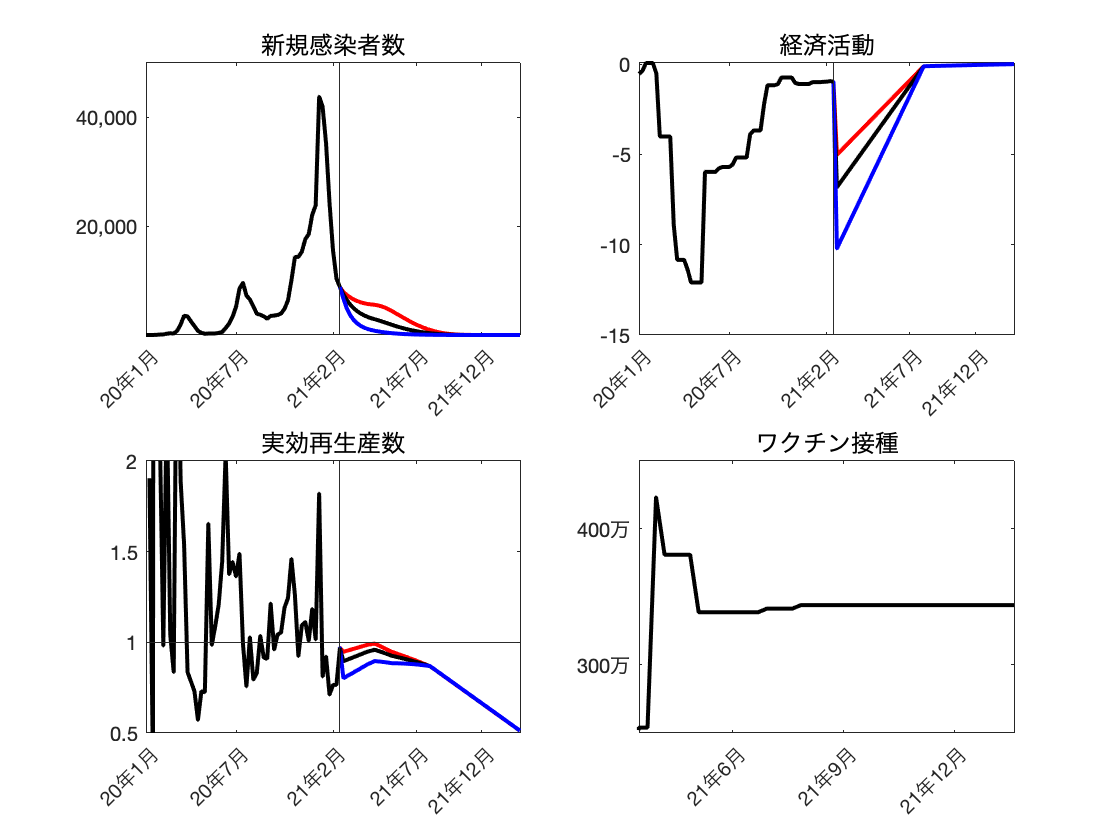

for i = 1:length(AlphaVals)
    alphaT = zeros(SimPeriod,1);
    alphaT(1:26) = flip(0:0.01*AlphaVals(i)*4/(26-1):(0.01*AlphaVals(i)*4))';
    SimGDP = referenceGDP(Tdata+1:Tdata+length(alphaT)).*(1-alphaT);
    [CD,AA,SimData,SimN]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,h,k,POP0,hconstant);
    AlphaIndexVariables(:,:,i) = [SimData(1:end-1,:),SimN,SimGDP];
end

Past = [N,GDP,ERN,zeros(Tdata,1)];
VarList2 = ["N","Y","ERN","VShots"];
VarName2 = ["New infections","Output (deviation from the reference path)","Effective reproduction number","Newly vaccinated persons"];
VarName2_jp = ["新規感染者数","経済活動","実効再生産数","ワクチン接種"];

for l = 1:2
    if l == 1
        figure(5)
    elseif l == 2
        figure(51)
    end
    for j = 1:4
        subplot(2,2,j)
        for i = 1:length(AlphaVals)
            
            %     alphaT = flip(0:0.01*AlphaVals(i)*2/(SimPeriod-1):(0.01*AlphaVals(i)*2))';
            alphaT = zeros(SimPeriod,1);
            alphaT(1:26) = flip(0:0.01*AlphaVals(i)*4/(26-1):(0.01*AlphaVals(i)*4))';
            %     alphaT = 0.01*AlphaVals(i)*ones(SimPeriod,1);
            if hconstant == 0
                ERNT = (AlphaIndexVariables(:,1,i)/POP0).*(((1+h*alphaT).^k).*betaT)./(gammaT+deltaT);
            elseif hconstant == 1
                ERNT = (AlphaIndexVariables(:,1,i)/POP0).*(((1+(h(2)/h(1))*alphaT).^k).*betaT)./(gammaT+deltaT);
            end
            ProjectedData = [AlphaIndexVariables(:,5,i),AlphaIndexVariables(:,6,i),ERNT,VShots];
            CombinedData = [Past;ProjectedData];
            
            if j==2
                temp=100*(CombinedData(:,j)-referenceGDP(1*length(CombinedData(:,j))))./referenceGDP(1*length(CombinedData(:,j)));
                if i==1
                    plot(temp,'r','LineWidth',2)
                elseif i==2
                    plot(temp,'k','LineWidth',2)
                elseif i==3
                    plot(temp,'b','LineWidth',2)
                end
                hold on
                plot(temp(1:Tdata),'k','LineWidth',2)
                hold on
            elseif j==4
                plot(CombinedData(:,j),'k','LineWidth',2)
            else
                if i==1
                    plot(CombinedData(:,j),'r','LineWidth',2)
                elseif i==2
                    plot(CombinedData(:,j),'k','LineWidth',2)
                elseif i==3
                    plot(CombinedData(:,j),'b','LineWidth',2)
                end
                hold on
                plot(Past(:,j),'k','LineWidth',2)
                hold on
            end
            xlim([1 Tdata+SimPeriod])
            if l == 1
                if j==2
                    title({'Output';'(deviation from reference level)'},'FontWeight','normal','FontSize',12)
                else
                    title(VarName2(j),'FontWeight','normal','FontSize',12)
                end
            elseif l == 2
                title(VarName2_jp(j),'FontWeight','normal','FontSize',12)
            end
            xline(Tdata);
            xticks([1 27 55 79 98])
            if l == 1
                xticklabels( {'Jan-20','Jul-20','Feb-21','Jul-21','Dec-21'} )
            elseif l == 2
                xticklabels( {'20年1月','20年7月','21年2月','21年7月','21年12月'} )
            end
            xtickangle(45)
            if j == 1
                yticks([2e4 4e4 6e4 8e4 10e4 12e4 14e4]);
                ax = gca;
                ax.YAxis.Exponent = 0;
                ytickformat('%,6.0f')
            end
            if j == 3
                ylim([0.5 2]);
                yline(1);
            end
            if j == 4
                xlim([Tdata+8,Tdata+SimPeriod])
                yticks([1e6 2e6 3e6 4e6]);
                xticks([63 76 89 102])
                if l == 1
                    yticklabels({'1M','2M','3M','4M'});
                    xticklabels({'Mar-21','Jun-21','Sep-21','Dec-21'})
                elseif l == 2
                    yticklabels({'100万','200万','300万','400万'});
                    xticklabels({'21年3月','21年6月','21年9月','21年12月'})
                end
            end
            hold on
        end
        
        %    alpha2 = [alpha;alphaT];
        %    beta2 = [beta;betaT];
        %    if hconstant == 0
        %    beta_tildeT = betaT.*(1+h*alphaT).^k;                                      % raw infection rate
        %    elseif hconstant == 1
        %    beta_tildeT = betaT.*(h(1)+h(2)*alpha).^k;
        %    beta_tildeT = betaT.*(1+(h(2)/h(1))*alphaT).^k;
        %    end
        %    beta_tilde2 = [beta_tilde;beta_tildeT];
        %    ERN2 = [ERN;ERNT];
        %    delta2 = [delta;deltaT];
        %    V2 = [zeros(Tdata,1);V];
        %    figure(101)
        %    %set(gcf,'Position',[100,100,800,500])
        %    for j = 1:length(ParamList2)
        %        subplot(2,2,j)
        %        plot(eval(ParamList2(j)),'k','LineWidth',2)
        %        xlim([1 Tdata+SimPeriod])
        %        title(ParamName(j),'Interpreter','latex','FontSize',11,'FontWeight','normal')
        %        xline(Tdata);
        %        xticks([1 27 53 79 98])
        %        xticklabels( {'Jan-20','Jul-20','Jan-21','Jul-21','Dec-21'} )
        %        xtickangle(45)
        %        if j == 2
        %            ylim([0,2])
        %        end
        %        if j == 3
        %            ylim([0,5])
        %        end
        %        if j == 4
        %            ylim([0,0.1])
        %        end
        %        hold on
        %    end
    end
end



%--- Trade-off figure (baseline) ---%
% figure(102)
% plot(100*AverageAlpha,CumD,'k','LineWidth',2)
% xlabel('Output Loss (%)','FontSize',fs)
% ylabel('Cumlative Deaths','FontSize',fs)
% xlim(xlim_tradeoff);
% yline(D(end-2),'r--','LineWidth',1.5);
% grid on
% ax = gca;
% ax.YAxis.FontSize = fs;
% ax.XAxis.FontSize = fs;
% ax.YAxis.Exponent = 0;
% ytickformat('%,6.0f')

%--- Trade-off figure (lag) ---%
% figure(8)
% plot(100*AverageAlpha,CumD,'k','LineWidth',2,'DisplayName','January 17th, 2021')
% legend('baseline')
% hold on
% for i = 1:length(wl)
%     wlag = wl(i);
%     if wlag == 1
%         plot(100*LagResults(2,:,i),LagResults(1,:,i),'r','LineWidth',2,'DisplayName',sprintf('%.0f week ago',wlag))
%     else
%         plot(100*LagResults(2,:,i),LagResults(1,:,i),'b','LineWidth',2,'DisplayName',sprintf('%.0f weeks ago',wlag))
%     end
%     hold on
% end
% hold off
% xlabel('Output Loss (%)','FontSize',fs)
% ylabel('Cumlative Deaths','FontSize',fs)
% xlim(xlim_tradeoff);
% ylim([0 50000]);
% xline(AverageAlpha2020,'LineWidth',1.5,'HandleVisibility','off');
% text(3.5,100000,{'Output loss';'      in 2020'},'FontSize',16);
% ax = gca;
% ax.YAxis.FontSize = fs;
% ax.XAxis.FontSize = fs;
% ax.YAxis.Exponent = 0;
% ytickformat('%,6.0f')
% lgd = legend;
% lgd.NumColumns = 1;
% lgd.FontSize = 15;
% %lgd.Location = 'north';
% grid on

%--- Trade-off figures with sensitivity analysis ---%
% SensitivityTitle = ["\beta","h","k","Vaccine pace"];
% SensitivitySaveTitle = ["beta","h","k","VacPace"];
% SensitivityLegend = {["5% higher","baseline","5% lower"], ["20% lower", "baseline", "20% higher"], ["1.5","2 (baseline)","2.5"], ...
%     ["0.5*baseline","baseline","2*baseline"]};
% for i = 1:length(SensitivityTitle)
%     figure(7)
%     set(gcf,'Position',[100,100,600,500])
%     subplot(2,2,i)
%     for j = 1:3
%         if j == 1
%             plot(TargetAlpha,SA(j,:,i),'b--','LineWidth',1.5)
%         elseif j == 2
%             plot(TargetAlpha,SA(j,:,i),'k-','LineWidth',1.5)
%         elseif j == 3
%             plot(TargetAlpha,SA(j,:,i),'r-.','LineWidth',1.5)
%         end
%         hold on
%     end
%     xlabel('Output Loss (%)','FontSize',14)
%     ylabel('Cumlative Deaths','FontSize',14)
%     ax = gca;
%     ax.YAxis.FontSize = 14;
%     ax.XAxis.FontSize = 14;
%     ax.YAxis.Exponent = 0;
%     ytickformat('%,6.0f')
%     xlim(xlim_tradeoff);
%     legend(SensitivityLegend{i},'FontSize',13)
%     title(SensitivityTitle(i),'FontSize',fs,'FontWeight','normal')
%     grid on
%     %saveas(figure(10+i),[home 'Figures/Paper/' char(SensitivitySaveTitle(i)) 'Sensitivity.png']);
%     hold off;
% end

%--- Counterfactual analysis for 2020 (multiplicative deviation of alpha)---%
% sw = 2;
% IV_CF = [S(sw),I(sw),R(sw),D(sw)];
% AlphaDeviation2 = 0.5:0.01:1.3;
% CF2 = zeros(2,length(AlphaDeviation2));
% for i = 1:length(AlphaDeviation2)
%     alpha_CF2 = alpha(sw:end-2)*AlphaDeviation2(i);
%     [CF2(1,i),CF2(2,i)]=Covid_projection(IV_CF,alpha_CF2,beta(sw:end-2),gamma*ones(Tdata-sw-1,1),delta(sw:end-2),zeros(Tdata-sw-1,1),h,k,POP0,hconstant);
% end
% figure(9)
% wedge = 100*mean(alpha(2:end-2))-AverageAlpha2020;
% plot(100*CF2(2,:)-wedge,CF2(1,:),'-ok','LineWidth',2,'MarkerIndices',find(AlphaDeviation2==1),'MarkerSize',15,'MarkerFaceColor','red','MarkerEdgeColor','none')
% xlabel('Output Loss (%)','FontSize',18)
% ylabel('Cumlative Deaths','FontSize',18)
% xlim([3,5]);
% grid on
% ax = gca;
% ax.YAxis.FontSize = 18;
% ax.XAxis.FontSize = 18;
% ax.YAxis.Exponent = 0;
% ytickformat('%,6.0f')
% 
% slope = mean([(CF2(1,51)-CF2(1,50))/(100*(CF2(2,51)-CF2(2,50))),(CF2(1,52)-CF2(1,51))/(100*(CF2(2,52)-CF2(2,51)))]);
% SVL = (POP0/slope)/100;


%%%%%%%%%%%%%%%%% Uncertainty band for the tradeoff curve %%%%%%%%%%%%%%%%%
char(datetime('today','Format','yyyMMdd'))

ans = '20210302'

if iPC==1
    LastD = load(['..\Covid19OutputJapan.github.io\archives\' LastWeek '\Japan' LastWeek '.mat']);
    Last2D = load(['..\Covid19OutputJapan.github.io\archives\' Last2Week '\Japan' Last2Week '.mat']);
else
    LastD = load(['../Covid19OutputJapan.github.io/archives/' LastWeek '/Japan' LastWeek '.mat']);
    Last2D = load(['../Covid19OutputJapan.github.io/archives/' Last2Week '/Japan' Last2Week '.mat']);
end

Error using load
'../Covid19OutputJapan.github.io/archives/20210216/Japan20210216.mat' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes

Change the MATLAB current folder or add its folder to the MATLAB path.


%--- Uncertainty-band parameters ---%
beta_se  = std(beta_sample)/sqrt(length(beta_sample));
delta_se= std(delta_sample)/sqrt(length(delta_sample));
%"h_se" is computed above.

if iDrawUB==0
    
    BetaValsUB = beta_average+beta_se*[-1,-0.75, -0.5, -0.25, 0, 0.25, 0.5, 0.75, 1];
    DeltaValsUB = delta_average+delta_se*[-1,-0.75, -0.5, -0.25, 0, 0.25, 0.5, 0.75, 1];
    HValsUB = h+h_se*[1,0.75,0.5,0.25, 0, -0.25, -0.5, -0.75, -1];
    UB = zeros(length(BetaValsUB),length(TargetAlpha));    % matrix to contain the results of uncertainty-band analysis
    
    for i = 1:length(TargetAlpha)
        %     alphaT = flip(0:0.01*TargetAlpha(i)*2/(SimPeriod-1):(0.01*TargetAlpha(i)*2))';
        alphaT = zeros(SimPeriod,1);
        alphaT(1:26) = flip(0:0.01*TargetAlpha(i)*4/(26-1):(0.01*TargetAlpha(i)*4))';
        for j = 1:length(BetaValsUB)
            betaS  = BetaValsUB(j)*ones(SimPeriod,1);
            %         deltaS = DeltaValsUB(j)*ones(SimPeriod,1);
            % New delta path as of 2021 01/26
            delta_averageS = DeltaValsUB(j);
            delta_ssS = delta_averageS*(0.09/1.27);
            deltaS = delta_averageS*ones(SimPeriod,1);
            deltaS(VacStart+3:VacStart+3+9+13) = delta_averageS:(delta_ssS-delta_averageS)/22:delta_ssS;
            deltaS(VacStart+3+9+13+1:end) = delta_ssS;
            HS = HValsUB(:,j);
            [UB(j,i)]=Covid_projection(InitialValues,alphaT,betaS,gammaT,deltaS,V,HS,k,POP0,hconstant);
        end
    end
    
    Y1UB = zeros(length(AverageAlpha),9);
    X1UB = 100*AverageAlpha;
    Y1UB(:,1)= UB(1,:);
    for iUB=2:9
        Y1UB(:,iUB)= UB(iUB,:)-UB(iUB-1,:);
    end
    
    %--- Trade-off figure with UB (baseline) ---%
    figure(6)
    AreaUB=area(X1UB,Y1UB,0);
    set(AreaUB(1),'FaceColor',[1 1 1])
    set(AreaUB(2),'FaceColor',[0.9 0.9 0.9])
    set(AreaUB(3),'FaceColor',[0.8 0.8 0.8])
    set(AreaUB(4),'FaceColor',[0.7 0.7 0.7])
    set(AreaUB(5),'FaceColor',[0.65 0.65 0.65])
    set(AreaUB(6),'FaceColor',[0.65 0.65 0.65])
    set(AreaUB(7),'FaceColor',[0.7 0.7 0.7])
    set(AreaUB(8),'FaceColor',[0.8 0.8 0.8])
    set(AreaUB(9),'FaceColor',[0.9 0.9 0.9])
    hold on
    for iUB=1:9
        set(AreaUB(iUB),'LineStyle','none')
    end
    plot(X1UB,CumD,'k','LineWidth',1.5)
    xlabel('Output Loss (%)','FontSize',16)
    ylabel('Cumlative Deaths','FontSize',16)
    xlim(xlim_tradeoff);
    ylim([0 30000]);
    xline(AverageAlpha2020,'LineWidth',1.5);
    text(3.5,150000,{'Output loss';'      in 2020'},'FontSize',16);
    yline(D(end-2),'r-','LineWidth',1.5);
    grid on
    ax = gca;
    ax.YAxis.FontSize = 16;
    ax.XAxis.FontSize = 16;
    ax.YAxis.Exponent = 0;
    ytickformat('%,6.0f')
    
elseif iDrawUB==1
    
    %%%%%%%%%%%%%%%%% Uncertainty band for the tradeoff curve (with simulation) %%%%%%%%%%%%%%%%%
    UB2=zeros(9,Nsim);    % matrix to contain the results of uncertainty-band analysis
    
    h1=h(1);
    h2=h(2);
    h_se1=h_se(1);
    h_se2=h_se(2);
    
    
    for i = 1:length(TargetAlpha)
        %    alphaT = flip(0:0.01*TargetAlpha(i)*2/(SimPeriod-1):(0.01*TargetAlpha(i)*2))';
        alphaT = zeros(SimPeriod,1);
        alphaT(1:26) = flip(0:0.01*TargetAlpha(i)*4/(26-1):(0.01*TargetAlpha(i)*4))';
        parfor j = 1:Nsim
            %    for j = 1:Nsim
            betaS  = normrnd(beta_average,beta_se)*ones(SimPeriod,1);
            %         deltaS = normrnd(delta_average,delta_se)*ones(SimPeriod,1);
            % New delta path as of 2021 01/26
            delta_averageS = normrnd(delta_average,delta_se);
            
            [V,deltaS,VT,real_pace] = vaccine_path(pace,SimPeriod,medical,elderly,ordinary,medical_start,elderly_start,4,0.9,delta_averageS,elderly_total);

%             
%             delta_ssS = delta_averageS*(0.09/1.27);
%             deltaS = delta_averageS*ones(SimPeriod,1);
%             deltaS(VacStart+3:VacStart+3+9+13) = delta_averageS:(delta_ssS-delta_averageS)/22:delta_ssS;
%             deltaS(VacStart+3+9+13+1:end) = delta_ssS;
%             
            %        HS(1) = normrnd(h(1),h_se(1)); % It does not work well with parfor
            %        HS(2) = normrnd(h(2),h_se(2)); % It does not work well with parfor
            HS1 = normrnd(h1,h_se1);
            HS2 = normrnd(h2,h_se2);
            HS=[HS1,HS2];
            [UB2(j,i)]=Covid_projection(InitialValues,alphaT,betaS,gammaT,deltaS,V,HS,k,POP0,hconstant);
        end
    end
    
    UBp=zeros(9,length(TargetAlpha));    % matrix to contain the results of uncertainty-band analysis
    Y1UB = zeros(length(AverageAlpha),9);
    X1UB = 100*AverageAlpha;
    for i = 1:length(TargetAlpha)
        UBp(:,i)=prctile(UB2(:,i),[10 20 30 40 50 60 70 80 90]);
    end
    Y1UBp(:,1)= UBp(1,:);
    for iUB=2:9
        Y1UBp(:,iUB)= UBp(iUB,:)-UBp(iUB-1,:);
    end
    
    
    for l = 1:2
        if l == 1
            figure(66)
        elseif l == 2
            figure(661)
        end
        AreaUBp=area(X1UB,Y1UBp,0)
        set(AreaUBp(1),'FaceColor',[1 1 1],'HandleVisibility','off')
        set(AreaUBp(2),'FaceColor',[0.9 0.9 0.9],'HandleVisibility','off')
        set(AreaUBp(3),'FaceColor',[0.8 0.8 0.8],'HandleVisibility','off')
        set(AreaUBp(4),'FaceColor',[0.7 0.7 0.7],'HandleVisibility','off')
        set(AreaUBp(5),'FaceColor',[0.65 0.65 0.65],'HandleVisibility','off')
        set(AreaUBp(6),'FaceColor',[0.65 0.65 0.65],'HandleVisibility','off')
        set(AreaUBp(7),'FaceColor',[0.7 0.7 0.7],'HandleVisibility','off')
        set(AreaUBp(8),'FaceColor',[0.8 0.8 0.8],'HandleVisibility','off')
        set(AreaUBp(9),'FaceColor',[0.9 0.9 0.9],'HandleVisibility','off')
        hold on
        for iUB=1:9
            set(AreaUBp(iUB),'LineStyle','none')
        end
        if l == 1
            plot(X1UB,CumD,'k','LineWidth',2,'DisplayName','This week')
            hold on
            % result from last week with current specification %
%             wlag = 1;
%             plot(100*LagResults(2,:,1),LagResults(1,:,1),'r--','LineWidth',1.5,'DisplayName','1 week ago (with current specification)')
%             hold on
            plot(100*LastD.AverageAlpha,LastD.CumD,'r','LineWidth',1.5,'DisplayName','1 week ago')
            hold on
%             plot(100*LastD.LagResults(2,:,1),LastD.LagResults(1,:,1),'b','LineWidth',1.5,'DisplayName','2 weeks ago')
              plot(100*Last2D.AverageAlpha,Last2D.CumD,'b','LineWidth',1.5,'DisplayName','2 weeks ago')
        elseif l == 2
            plot(X1UB,CumD,'k','LineWidth',2,'DisplayName','今週')
            hold on
            % result from last week with current specification %
%             wlag = 1;
%             plot(100*LagResults(2,:,1),LagResults(1,:,1),'r--','LineWidth',1.5,'DisplayName','１週間前（現在の仮定）')
%             hold on
            plot(100*LastD.AverageAlpha,LastD.CumD,'r','LineWidth',1.5,'DisplayName','１週間前')
            hold on
%             plot(100*LastD.LagResults(2,:,1),LastD.LagResults(1,:,1),'b','LineWidth',1.5,'DisplayName','２週間前')
            plot(100*Last2D.AverageAlpha,Last2D.CumD,'b','LineWidth',1.5,'DisplayName','２週間前')
        end
        % for i = 1:length(wl)
        %     wlag = wl(i);
        %     if wlag == 1
        %     plot(100*LagResults(2,:,i),LagResults(1,:,i),'r','LineWidth',1.5,'DisplayName',sprintf('%.0f week ago',wlag))
        %     else
        %     plot(100*LagResults(2,:,i),LagResults(1,:,i),'b','LineWidth',1.5,'DisplayName',sprintf('%.0f weeks ago',wlag))
        %     end
        %     hold on
        % end
        hold off
        if l == 1
            xlabel('Output Loss (%)','FontSize',16)
            ylabel('Cumulative Deaths','FontSize',16)
%             xline(AverageAlpha2020,'k','LineWidth',1.5,'HandleVisibility','off');
%             text(3.5,150000,{'Output loss';'      in 2020'},'FontSize',16);
        elseif l == 2
            xlabel('経済損失 (%)','FontSize',16)
            ylabel('累計死亡者数','FontSize',16)
%             xline(AverageAlpha2020,'k','LineWidth',1.5,'HandleVisibility','off');
%             text(3.5,150000,{'????';'     ?2020??'},'FontSize',16);
        end
        
        yline(D(end),'k--','LineWidth',1.5,'HandleVisibility','off');
        xlim(xlim_tradeoff);
        ylim([5000 20000]);
        grid on
        lgd = legend;
        lgd.NumColumns = 1;
        lgd.FontSize = 15;
        ax = gca;
        ax.YAxis.FontSize = 16;
        ax.XAxis.FontSize = 16;
        ax.YAxis.Exponent = 0;
        ytickformat('%,6.0f')
    end
%     
%     %%%%%%%%%%%%%%%%% Chart of the week
%     for l = 1:2
%         if l == 1
%             figure(666)
%         elseif l == 2
%             figure(6661)
%         end
%         AreaUBp=area(X1UB,Y1UBp,0)
%         set(AreaUBp(1),'FaceColor',[1 1 1],'HandleVisibility','off')
%         set(AreaUBp(2),'FaceColor',[0.9 0.9 0.9],'HandleVisibility','off')
%         set(AreaUBp(3),'FaceColor',[0.8 0.8 0.8],'HandleVisibility','off')
%         set(AreaUBp(4),'FaceColor',[0.7 0.7 0.7],'HandleVisibility','off')
%         set(AreaUBp(5),'FaceColor',[0.65 0.65 0.65],'HandleVisibility','off')
%         set(AreaUBp(6),'FaceColor',[0.65 0.65 0.65],'HandleVisibility','off')
%         set(AreaUBp(7),'FaceColor',[0.7 0.7 0.7],'HandleVisibility','off')
%         set(AreaUBp(8),'FaceColor',[0.8 0.8 0.8],'HandleVisibility','off')
%         set(AreaUBp(9),'FaceColor',[0.9 0.9 0.9],'HandleVisibility','off')
%         hold on
%         for iUB=1:9
%             set(AreaUBp(iUB),'LineStyle','none')
%         end
%         if l == 1
%             plot(X1UB,CumD,'k','LineWidth',2,'DisplayName','Baseline')
%             hold on
%             % 4 in the last element of SA means the sensitivity w.r.t vaccine pace
%             plot(TargetAlpha,SA(3,:,4),'r-','LineWidth',2,'DisplayName','Faster Vaccine Distribution')
%         elseif l == 2
%             plot(X1UB,CumD,'k','LineWidth',2,'DisplayName','基本仮定（ワクチン毎週400万本）')
%             hold on
%             plot(TargetAlpha,SA(3,:,4),'r-','LineWidth',2,'DisplayName','ワクチン毎週800万本')
%         end
%         hold off
%         if l == 1
%             xlabel('Output Loss (%)','FontSize',16)
%             ylabel('Cumulative Deaths','FontSize',16)
% %             text(3.5,150000,{'Output loss';'      in 2020'},'FontSize',16);
%         elseif l == 2
%             xlabel('経済損失 (%)','FontSize',16)
%             ylabel('累計死亡者数','FontSize',16)
% %             text(3.5,150000,{'????';'     ?2020??'},'FontSize',16);
%         end
%         xline(AverageAlpha2020,'k','LineWidth',1.5,'HandleVisibility','off');
%         xlim(xlim_tradeoff);
%         ylim([0 30000]);
%         yline(D(End2020),'k--','LineWidth',1.5,'HandleVisibility','off');
%         grid on
%         lgd = legend;
%         lgd.NumColumns = 1;
%         lgd.FontSize = 15;
%         ax = gca;
%         ax.YAxis.FontSize = 16;
%         ax.XAxis.FontSize = 16;
%         ax.YAxis.Exponent = 0;
%         ytickformat('%,6.0f')
%     end
end % end of if-else statement for iDrawUB



%--- Save all figures ---%
if figure_save == 1
    %saveas(figure(1),[home  '\Figures\NewCases.png']);
    %saveas(figure(2),[home  '\Figures\MobilityGDPLine.png']);
    %saveas(figure(3),[home  '\Figures\Parameters.png']);
    %saveas(figure(4),[home  '\Figures\Variables.png']);
    if iPC==1
        saveas(figure(5),[home  'Figures\VariablesProjection.png']);
        saveas(figure(51),[home  'Figures\VariablesProjection_jp.png']);
    else
        saveas(figure(5),[home  'Figures/VariablesProjection.png']);
        saveas(figure(51),[home  'Figures/VariablesProjection_jp.png']);
    end

    
    %saveas(figure(6),[home  '\Figures\BaselineTradeoffUB.png']);
%     saveas(figure(10),[home 'Figures/ForecastErrors.png']);
%     saveas(figure(101),[home 'Figures/ForecastErrors_jp.png']);
    
    if iPC==1
        saveas(figure(66),[home  'Figures\BaselineTradeoffUBp.png']);
        saveas(figure(661),[home  'Figures\BaselineTradeoffUBp_jp.png']);
    else
        saveas(figure(66),[home  'Figures/BaselineTradeoffUBp.png']);
        saveas(figure(661),[home  'Figures/BaselineTradeoffUBp_jp.png']);
    end

%     saveas(figure(666),[home  'Figures/ChartOfTheWeek.png']);
%     saveas(figure(6661),[home  'Figures/ChartOfTheWeek_jp.png']);
    
    %saveas(figure(7),[home  '\Figures\Sensitivity.png']);
    %saveas(figure(8),[home  '\Figures\LaggedTradeoff.png']);
    %saveas(figure(9),[home  '\Figures\CF_multiplicative.png']);
    
   
    
    %saveas(figure(100),[home '\Figures\MobilityGDPScatter.png']);
    %saveas(figure(101),[home '\Figures\ParametersProjection.png']);
    %saveas(figure(102),[home '\Figures\BaselineTradeoff.png']);
end

clear UB2

if mat_save==1
    save([pref char(datetime('today','Format','yyyMMdd')) '.mat'])
end